# Landing Length Estimate - Roskam Approximate Method

clear
clc
assum=strings(0); %Using this to collect all assumptions
g=32.17; %gravity ft/s2

#### References:

Roskam - [https://drive.google.com/file/d/1Hkm2aE2Njfvadv5QCgk-oXgR9W_zMkL3/view?usp=sharing](https://drive.google.com/file/d/1Hkm2aE2Njfvadv5QCgk-oXgR9W_zMkL3/view?usp=sharing)

## Numbers from performance metrics report

Balanced Field Length:	10,654 ft

Takeoff Field Length:	10,941 ft

Landing Field Length:	10,723 ft

#### Takeoff parameters

PLR Throttle Assumption:	-0                        %What is this?

Altitude at distance 21325.0ft	    948ft         

Approachthrottle=0.253;         %Should this be my idle thrust percent instead?
LD_ratio=5.77;                  %Approach Lift/Drag ratio	
V1=182;                         %keas
V2=211;                         %keas
V_A=162;                        %keas Vapproach
idle_percent=0.05;
T=37350*idle_percent;       %converting nominal thrust to idle 
W=412224*32.174;             %converting Max Takeoff from Lbm to Lbf
assum(length(assum)+1)="FLAG What idle thrust do I use here? check conversion";
assum(length(assum)+1)="FLAG What weight do I use here? check conversion";

## Roskam Approximation

From Roskam page 479, the goal is to find:

$S_{\textrm{LA}}$* (Landing distance cover in the air)*

$S_{\textrm{LR}}$* (Landing distance during rotation)*

$S_{\textrm{LNGR}}$* (Landing distance covered nose wheel on ground)*

$S_L =S_{\textrm{LA}} +S_{\textrm{LR}} +S_{\textrm{LNGR}}$* (Total landing distance)*

mu_gBrake=0.6;          %Based on table 10.3 below. 
assum(length(assum)+1)="Braking coefficient is XXX based on XX with no derate or anti-skid eff sim-ed";

% mu_gBrake=0.45;       %Derate braking coeff for passenger comfort
mu_g=mu_gBrake;         %In the math, rolling friction is used for the nose gear.. however we will have brakes in the NG as well

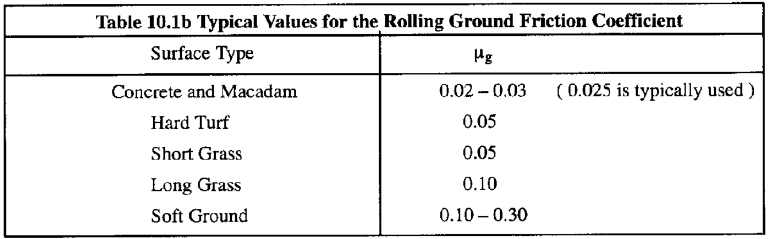

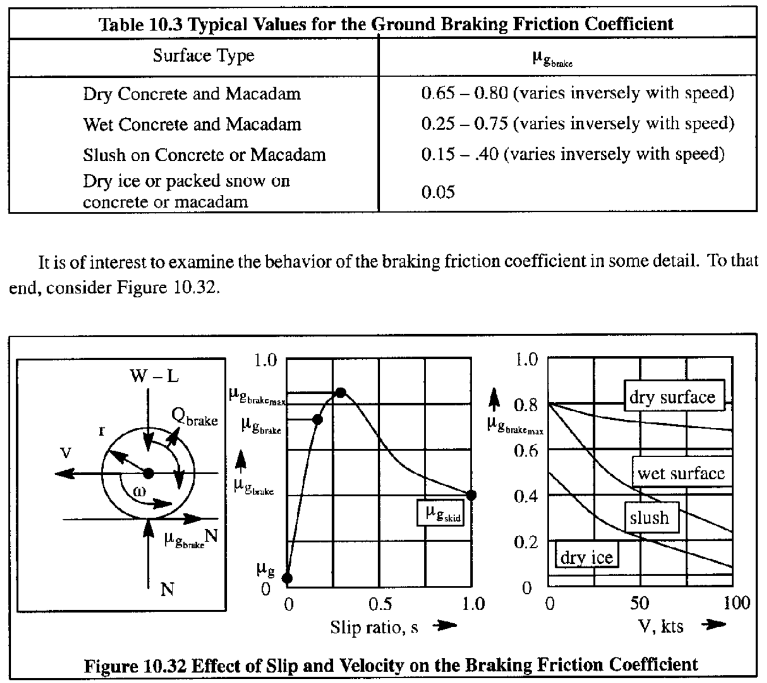

Since we don't know $V_{s_{\textrm{approach}} }$ I estimate it using Roskam's two formulas below


$$V_A \ge 1.3{V_s}_{approach}$$
  


$$V_{TD}  \approx 1.15{V_s}_{approach}$$


Therefore,


$$V_{TD}  \leq 0.885V_A$$


I will keep he highest rough estimate


$$V_{TD}  \approx 0.885V_A$$


Vtd=0.885*V_A;  %Vtd estimate
assum(length(assum)+1)="Approximation on V_touchdown";
h_screen=50;    %Screen height in ft

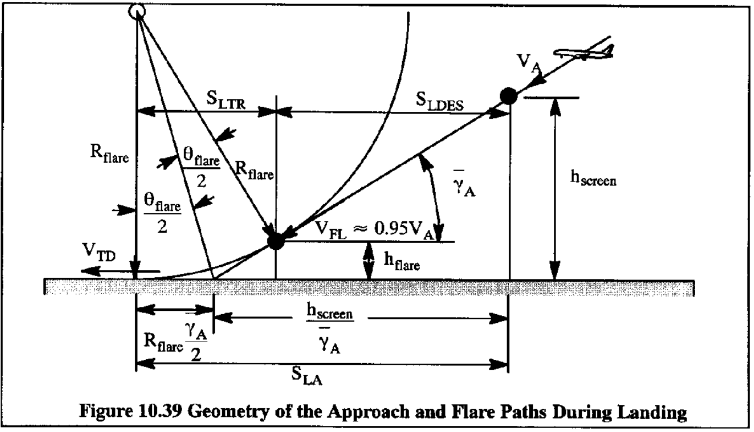

## Solving for $S_{\textrm{LA}}$

Vfl=0.95*V_A; % [10.108] Flare Speed


nfl=1.06; %load factor on flare, depends on pilot technique and is usually 1.04 to 1.08
assum(length(assum)+1)="Approximation nfl, Pilot Technique";

Rflare=Vfl^2/(g*(nfl-1)); %[10.107] flare radius

DvsLratio=1/LD_ratio;
ya=-(T/W)+(DvsLratio); %[10.81] OR a value of 3deg or higher may be assumed
assum(length(assum)+1)="Approximation ya, approach flight path angle,";

Sla=h_screen/ya+Rflare*ya/2

Sla = 1.3512e+03

## Solving for $S_{\textrm{LR}}$

tlr=3; %[10.109] rotation duration assumption
assum(length(assum)+1)="Approximation tlr, time for landing rotation";

Slr=Vtd*tlr; %[10.110] distance covered during ground rotation
assum(length(assum)+1)="Approximation on Slr, distance during ground rotation; Vtd=Vlr";


## Solving for $S_{\textrm{LNGR}}$

All equations based on a modified version of equation [10.75]

assum(length(assum)+1)="During landing Vlr = Vrd";
assum(length(assum)+1)="Automatic braking";
assum(length(assum)+1)="Runway inclination, phi=0";
assum(length(assum)+1)="No wind, Vw=0";
assum(length(assum)+1)="Constant angle of attack, Cdg & Clg are independant of speed";

% A=2*g*((mu_gBrake-T/W)   -   (Nn/W)*(mu_gBrake-mu_g))   %[10.113] 
assum(length(assum)+1)="Line 48 I can just set mu_g=mu_gBrake";
%Mu_g is free rolling resistance, this is for the nose gear so we'll make it equal to Mu_gBrake
%Nn/W is ratio of nose gear ground reaction to weight and can be estimated as 0.8

% B=g*??*(Cdg-mu_gBrakeClg)/(W/S)                         %[10.114]

## Summing up, and adding FAR 25 safety factor

% Sl=Sla+Slr+Slngr
% SL_fieldlength=SL/0.6; %FAR25 FIND THIS REQUIREMENT

# ASSUMPTIONS

fprintf(2,'Assumptions in Code:\n');disp(assum');

Assumptions in Code:
    "FLAG What idle thrust do I use here? check conversion"
    "FLAG What weight do I use here? check conversion"
    "Braking coefficient is XXX based on XX with no derate or anti-skid eff sim-ed"
    "Approximation on V_touchdown"
    "Approximation nfl, Pilot Technique"
    "Approximation ya, approach flight path angle,"
    "Approximation tlr, time for landing rotation"
    "Approximation on Slr, distance during ground rotation; Vtd=Vlr"
    "During landing Vlr = Vrd"
    "Automatic braking"
    "Runway inclination, phi=0"
    "No wind, Vw=0"
    "Constant angle of attack, Cdg & Clg are independant of speed"
    "Line 48 I can just set mu_g=mu_gBrake"



# Needs a second look

Line 19: Does this really work after you trickle it down?

Line 42: Lots of difficulty in my SLNGR

                    -How can I get my C and D coeffs in ground effect?

                    -S value, and strange value Unfinished Implementation

# Needs Implementation

- I still need to add braking to nose gear

- I have not added provisions for wind

- I have not added provisions for tail/head wind

# Notes

Delta wing benefits from a huge drag during rotation